## **AASI HW0**

Po-Tao, Lin

B11501037

Date: 2025/09/10

clear; close all; clc;

### Part 1 Data setting

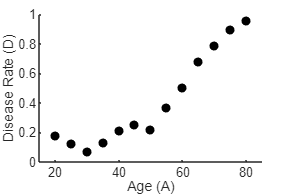

% original data
A = 20:5:80;                    %age
D = [0.18, 0.12, 0.07, 0.13, 0.21, 0.25, 0.22, 0.37, 0.50,...
    0.68, 0.79, 0.90, 0.96];    %disease rate
%---make figure
figure('Position',[100 100 600 400])
set(gcf, 'Color','White');
scatter(A,D,'k','filled','DisplayName','data')
xlabel('Age (A)');
ylabel('Disease Rate (D)');
xlim([15,85]); ylim([0,1])
exportgraphics(gca,'Fig1.pdf','ContentType','vector')

### Part 2 Model

#### Part 2-1 polynomial pattern


$$M_1 :\;\;{c_2 A}^2 +c_1 A+c_0 =D$$


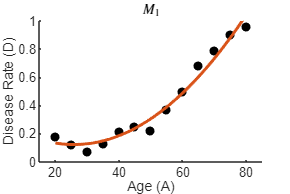

B1 = [A.^2; A; A.^0];
C1 = D/B1;
A_fit = linspace(min(A), max(A), 200);
model_poly = @(C,x) C(1)*x.^2+C(2)*x+C(3);

%---make figure
figure('Position',[100 100 600 400])
set(gcf, 'Color','White');
scatter(A,D,'k','filled','DisplayName','data')
hold on
xlabel('Age (A)');
ylabel('Disease Rate (D)');
plot(A_fit, model_poly(C1,A_fit),'linewidth',2,'DisplayName','M_1');
title('$M_1$','Interpreter','latex');xlim([15,85]); ylim([0,1])
exportgraphics(gca,'Fig2.pdf','ContentType','vector');

#### Part 2-2 slowing model


$$M_2 :\frac{p_3 }{1+p\left(2\right)\;\exp \;\left\lbrack p_1 A\right\rbrack }=D$$


model_exp = @(p, x) p(3) ./ (1 + p(2) * exp(p(1) * x)); % assumed form
p0 = [-0.1, 1, 1];   % first suggestion
% [lsqcurvefit] to fit curve
opts = optimoptions('lsqcurvefit','Display','iter');
lb = [-Inf, 0, 0];      % upperbound (a,b,c)
ub = [Inf, Inf, Inf];   % lowerbound (a,b,c)
p = lsqcurvefit(model_exp, p0, A, D, lb, ub, opts);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           5.15955                             7.06
     1          8            3.4168        0.402456            0.129      
     2         12           2.48865        0.459069             2.98      
     3         16           1.31831        0.257524            0.628      
     4         20           1.20408        0.112184            0.083      
     5         24           1.20116       0.0222118           0.0104      
     6         28           1.20116         9.01448           0.0104      
     7         32           1.03915         1.27456             1.45      
     8         36           1.03915         2.15581             1.45      
     9         40           1.03915        0.538952             1.45      
    10         44           1.03915        0.134738             1.45      
    11         48          0.946524      

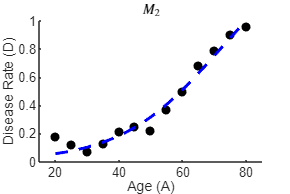


A_fit = linspace(min(A), max(A), 200);
D_fit = model_exp(p, A_fit);
%---make figure
figure('Position',[100 100 600 400])
set(gcf, 'Color','White');
scatter(A,D,'k','filled','DisplayName','data')
hold on
xlabel('Age (A)');
ylabel('Disease Rate (D)');
plot(A_fit, D_fit,'b--','linewidth',2,'DisplayName','M_2')
title('$M_2$','Interpreter','latex');xlim([15,85]); ylim([0,1])
exportgraphics(gca,'Fig3.pdf','ContentType','vector');

### Part 3 determine the goodness of fit

%--R^2
function RS = RScompute(D_model, D_origin)
    SS_res = sum((D_origin-D_model).^2);
    SS_tot = sum((D_origin-mean(D_origin)).^2);
    RS = 1-SS_res/SS_tot;
end
%--RMSE
function RMSE = RMSEcompute(D_model, D_origin)
    RMSE = sqrt(mean((D_model-D_origin).^2));
end
%
RS_poly = RScompute(model_poly(p,A),D);
RS_exp = RScompute(model_exp(p,A),D);

RMSE_poly = RMSEcompute(model_poly(p,A),D);
RMSE_exp = RMSEcompute(model_exp(p,A),D);